# Simpson's Rules

***Author****: Dr. Matthew Leineweber, San Jose State University*

## Introduction

In the previous lectures, the trapezoid rule was introduced as a means of numerically integrating either a known function $f(x)$ or a set of tabulated $(x_i,y_i)$ data representing some unknown $f(x)$. This technique is part of a wider group of integration methods, called *numerical quadrature*, that simplify the integral of $f(x)$ by approximating $f$ with a polynomial:


$$f_n(x)  = a_0 + a_1x + a_2x^2 + \dots + a_{n-1}x^{n-1} + a_nx^n$$


So that the integral of  $f_n(x)$ approximates the integral of $f$:


$$\int_a^b{f(x)dx} \approx \int_a^b{f_n(x) dx}$$


For the trapezoid rule, we used a first-order polynomial representation to define $f_1(x) = a_0 + a_1x$, where $a_1$ is defined as the slope of the line between $a$ and $b$, and is equal to:


$$a_1 =\frac{f(b)-f(a)}{b-a}$$


Using the point-slope formulation of the first-order polynomial produced the equation:


$$f_1(x)-f(a) = a_1(x-a)\ \rightarrow\ \ f_1(x) = \frac{f(b)-f(a)}{b-a}(x-a)+f(a)$$


We might note that this formulation of $f_1(x)$ is equivalent to the first-degree *Lagrange interpolating polynomial*

$f_n(x) = \sum\limits_{i=0}^n{L_i(x)f(x_i)$  where  $L_i(x) = \prod\limits_{\begin{array}{c} j=0 \\ j\neq i\end{array}}^n{\frac{x-x_j}{x_i-x_j}}$

Letting $n=1$ produces the expression:


$$f_1(x) = \frac{x-x_1}{x_0-x_1}f(x_0) + \frac{x-x_0}{x_1-x_0}f(x_1)$$


Letting $x_0 = a$ and $x_1=b$ simplifies our equation to the familiar form:


$$\begin{array}{rcl} f_1(x) & = & \frac{x-b}{a-b}f(a) + \frac{x-a}{b-a}f(b) 
\\ & = & \frac{x-a}{b-a}f(b)  - \frac{x-b}{b-a}f(a) 
\\ & = & \frac{x\left(f(b)-f(a)\right) -  af(b) + bf(a)}{b-a} \\ & = & \frac{f(b)-f(a)}{b-a}(x-a) +f(a) \end{array}$$


Therefore, our familiar integral approximation becomes:


$$\begin{array}{rcl} \int_a^b{f(x)dx} & \approx & \int_a^b{\left(\frac{f(b)-f(a)}{b-a}(x-a)+f(a)\right)dx 
\\ & = & \frac{f(b)-f(a)}{b-a}\int_a^b{(x-a)dx} + \int_a^b{f(a)dx}
\\ & = & \frac{f(b)-f(a)}{b-a}\left.\left(\frac{x^2}{2}-ax\right)\right|_a^b + \left. f(a) x\right|_a^b 
\\ & = & \frac{(b-a)(f(b)-f(a))}{2} + f(a)(b-a) 
\\ & = & \left(b-a\right)\frac{f(a)+f(b)}{2}\end{array}$$


We recognize this final expression as being equivalent to the area of a trapezoid of sides with length $f(a)$ and $f(b)$ and width $b-a$. 

While the trapezoid rule provides a convenient approximation for estimating the area under sections of $f(x)$ with little curvature, we saw that its accuracy drastically decreases as $(b-a)$ increases, and/or when $f(x)$ has a high degree of curvature on the interval $[a,b]$. We overcame this limitation by separating the interval $[a,b]$ into many sub-intervals and successively performing the trapezoid rule on each of these smaller segments, but this iterative process required many rounds of calculation.

An alternate approach to this multiple trapezoid rule is to use higher degree polynomials in our approximation of $f(x)$. That is, for our original approximation:


$$\int_a^b{f(x)dx} \approx \int_a^b{f_n(x) dx}$$


We can choose polynomials of degree $n>1$. In this module, we will explore two such polynomials: (1) a quadratic (second-order) polynomial, and (2) a cubic (third-order) polynomial. The resulting approximations are referred to as the Simpson's 1/3 rule and Simpson's 3/8 rule, respectively.

## Simpson's 1/3 rule

Following a parallel approach, we can let $f(x)\approx f_2(x)$, where $f_2(x)$ is the second-degree Lagrange Interpolating Polynomial for $f(x)$:


$$f_2(x) = \frac{(x-x_1)(x-x_2)}{(x_0-x_1)(x_0-x_2)}f(x_0) + \frac{(x-x_0)(x-x_2)}{(x_1-x_0)(x_1-x_2)}f(x_1) + \frac{(x-x_0)(x-x_1)}{(x_2-x_0)(x_2-x_1)}f(x_2)$$


Assuming that $x_1$ is at the midpoint between $x_0$ and $x_2$ and integrating this expression over the interval $[x_0,x_2]$ produces the approximation:


$$I \approx \int_a^b{f_2(x)dx} = \frac{h}{3}\left[f(x_0)+4f(x_1) + f(x_2)\right]$$


where $h=\frac{x_2-x_0}{2}$, the distance between neighboring points. For a single application of the Simpson's 1/3 rule, we can see that our integral approximation can be written as $I = \frac{h}{3}\left[f(a) + 4f(a+h)+f(b)\right]$. Comparing this formulation to our trapezoid rule approximation, we can immediately see that the Simpson's 1/3 rule requires evaluation of an additional point, $(x_1,f(x_1))$, on the interval $[a,b]$.

#### Activity 1: Visualizing Simpson's 1/3 rule

Play with the sliders below to select an interval $[a,b]$ over which to define the second-degree interpolating polynomial for $f(x)$. When selecting values for $a$ and $b$, consider the following:

- How does the accuracy of our interpolating polynomials change as $[a,b]$ increases? Decreases?

- How does the curvature of $f(x)$ over the interval $[a,b]$ affect the accuracy of the interpolating polynomial?

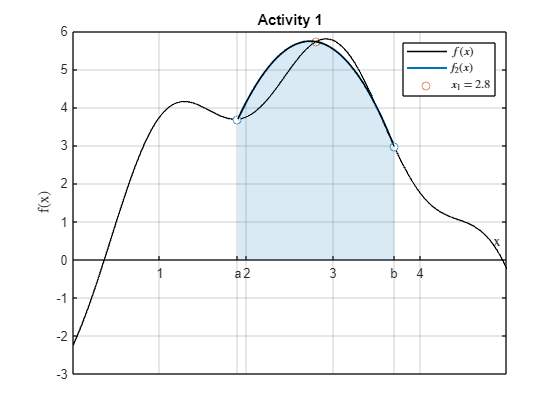

a = 1.9;
b = 3.7;
Activity1(a,b)

### Multiple applications of Simpson's 1/3 rule

Like the trapezoid rule, we can increase the accuracy of our Simpson's 1/3 rule integration by dividing our $[a,b]$ interval into $n$ sub-intervals of width


$$h = \frac{b-a}{n}$$


The total integral then becomes:


$$I = \int_{x_0}^{x_2}{f(x)dx} + \int_{x_2}^{x_4}{f(x)dx} + \dots + \int_{x_{n-2}}^{x_n}{f(x)dx}$$


Notice that each integral is computed over an interval of width $2h$. Substituting the Simpson's 1/3 rule formula for each of these integrals produces:


$$I \approx 2h\frac{f(x_0)+4f(x_1)+f(x_2)}{6} +  2h\frac{f(x_2)+4f(x_3)+f(x_4)}{6} + \dots +  2h\frac{f(x_{n-2})+4f(x_{n-1})+f(x_n)}{6}$$


Combining terms and substituting our definition of $h$ produces:


$$I \approx \left(b-a\right)\frac{f(x_0) + 4\sum\limits_{i=1,3,5\dots}^{n-1}{f(x_i)} + 2\sum\limits_{j=2,4,6\dots}^{n-2}{f(x_j)} + f(x_n)}{3n}$$


where $x_0=a$ and $x_n=b$. Notice that the first factor $(b-a)$ represents the width of the interval over which the integral is to be computed, and the fraction represents the average height of all the $f(x_k)$ points over that interval, for $k = 1,2,3,\dots,n$.

As with the trapezoid rule, we can see that formulating an algorithm to integrate with Simpson's 1/3 rule requires 5 steps:

- Defining an expression for $f(x)$

- Selecting the limits of integration, $a$ and $b$

- Selecting the number of intervals, $n$, and define $h = \frac{b-a}{n}$

- Summing the $f(x_i)$ values for even $i$ and the $f(x_j)$ values for odd $j$

- Calculate $I$ using the formula.

Steps 1-3 are all defined by the user, while steps 4 and 5 must be completed by the algorithm. While this process is very similar to the trapezoid rule, we see one major difference introduced by step 3. Namely, we must use a different summation depending on whether our current value $x_k$ is even or odd.

### Developing an algorithm for multiple applications of Simpson's 1/3 rule

We can convert our five-step process into pseudocode steps:

Consider the loop in the pseudocode. We can see that the values of $k$ will be:


$$k = 1,3,5,\dots,n-2$$


Therefore, recalling that our points $x_1, x_2, \dots, x_n$ are defined as:


$$x_1 = a+h \\ x_2 = a+2h \\ \vdots \\ x_n = a+nh$$


The expression `k*h` will return $h,3h,5h,\dots,(n-3)h$, which contains the $x_k$ terms for odd $k$. Similarly, the `(k+1)*h` expression will return the $x_k$ for even $k$: $2h,4h,\dots,(n-2)h$. Let's take a look at how these terms are affected by our selection of $n$.

n = 10

n = 10

T = Activity2(n)

T = 4×3 table
    k     x_k     x_(k+1)
    _    _____    _______

    1    "x_1"     "x_2" 
    3    "x_3"     "x_4" 
    5    "x_5"     "x_6" 
    7    "x_7"     "x_8" 


disp(T)

    k     x_k     x_(k+1)
    _    _____    _______

    1    "x_1"     "x_2" 
    3    "x_3"     "x_4" 
    5    "x_5"     "x_6" 
    7    "x_7"     "x_8" 



Notice that when $n$ is even, the final term in the x_(k+1) column always corresponds to $x_{n-2}$. However, when $n$ is odd, this final term corresponds to $x_{n-1}$, which means that our algorithm will no longer work, since we end up adding contributions from the $x_{n-1}$ term twice. **Therefore, we can conclude that our algorithm for the Simpson's 1/3 rule will only work when **$n$** is an even number of intervals.**

#### Activity 2: Algorithm for multiple applications of Simpson's 1/3 rule

In this activity, we will walk through the steps of using multiple applications of Simpson's 1/3 rule to integrate the expression:


$$f(x)=5\sin{\left(\frac{\pi}{10}x\right)}$$


over the interval $0\leq x \leq 10$. As a starting point, let's use $n=6$ intervals to visualize our approximation.

**Step 1:** Define an expression for $f(x)$ as an anonymous function named `fx`:

fx = @(x) 5*sin(pi/10*x);

**Step 2:** Define the limits of integration

a = 0;
b = 10;

**Step 3:  **Define the number of intervals $n$ and the interval width $h$

n = 6;
h = (b-a)/n;

Now that this user-defined information has been established, let's convert our pseudocode into actual MATLAB commands

% Define the first point in the integral f(a) [replace the expression for I]
I = fx(a);

% Loop through the points corresponding to x_1 to x_(n-2)
for k = 1:2:(n-2)
    % Add the new terms in the denominator
    I = I + 4*fx(k*h) + 2*fx((k+1)*h);
end

% Add 4*f(x_(n-1)) and 2*f(n)
I = I + 4*fx((n-1)*h) + fx(n*h);

% Multiply the numerator by h/3
I = (h/3)*I;

% Display the result
fprintf("I = %2.4f",I)

I = 31.8447

We can compare this result to the analytical solution:


$$I = \int_0^{10}{5\sin\left({\frac{\pi}{10}x}\right)dx} = \left.-\frac{50}{\pi}\cos{\left(\frac{\pi}{10}x\right)}\right|_0^{10} = \frac{100}{\pi}\approx 31.83$$


We see that our estimate is very accurate, even with a relatively small number of intervals. 

#### Activity 3: Creating a function for Simpson's 1/3 rule

Now that we have an algorithm for the Simpson's 1/3 rule, it is fairly straightforward to convert this algorithm into a function. As an exercise, look through the definition of the `Simpsons13` function at the end of this live script and compare it to the algorithm we developed in the previous section.

Let's see how our function compares to our previous algorithm.

**Task. **Uncomment the code below by removing the % and then run this section.

I = Simpsons13(fx,0,10,6)

I = 31.8447

### Simpson's 1/3 rule with discrete data

So far, we have always had a mathematical expression defining $f(x)$. However, it is often the case that we instead have tabulated $(x_i,y_i)$ data, where the underlying mathematical function is unknown. In this case, we have to make slight modifications to our algorithm. As long as our tabulated data has an odd number of evenly spaced $x_i$ points, we can simply let each $y_i$ point be equivalent to $f(x_i)$, so our equation becomes:


$$I\approx\left(b-a\right)\frac{y_0 + 4\sum\limits_{i=1,3,5\dots}^{n-1}{y_i} + 2\sum\limits_{j=2,4,6\dots}^{n-2}{y_j} + y_n}{3n}$$


where $n = N-1$ is equal to the number of intervals in the $(x_i,y_i)$ dataset, and $N$ is the number of points in the dataset. Refer to the `Simps13` function at the end of this module to see how the algorithm changed. Notice that we were able to get rid of the loop entirely by using indexing methods to directly select every other element in the $x$ and $y$ vectors.

x = 0:10;
y = [0 1.5451 2.9389 4.0451 4.7553 5.0000 4.7553 4.0451 2.9389 1.5451 0];

I = Simps13(x,y)

I = 31.8328

Looking at the `Simps13` function below, we can see that it operates much the same as `Simpsons13`, but rather than evaluating the $y$-points from a known $f(x)$ function, they are simply selected from the `y` input argument. Therefore, the algorithm used to perform this integration is identical to what would be used when calculating the integral by hand from a set of tabulated data.

While multiple applications of Simpson's 1/3 rule generally produces a more accurate estimate than the trapezoid rule, we can see that it still is limited by a few key assumptions. Namely, the intervals must be equispaced, and an odd number of points must be used. While the equispaced data requirement must remain in place for now, we combine an additional technique, called the Simpson's 3/8 rule, with the Simpson's 1/3 rule to enable evaluation of integrals with an odd number of intervals and an even number of points.

### Simpson's 3/8 rule

So far, we have seen the application of first-order (trapezoid rule) and second-order (Simpson's 1/3 rule) Lagrange polynomials to derive our numerical integration formulas. Recall that an $n^{th}$-order polynomial requires at least $n+1$ points to be fully defined, which is why the trapezoid rule requires at least two points, and the Simpson's 1/3 rule requires at least three points. It follows, therefore, that application of a third-order Lagrange polynomial would require at least $3+1 =4$ points. The derivation of this formula is much the same as for the Simpson's 1/3 rule, and follows from:


$$I = \int_a^b{f(x) dx} \approx \int_a^b{f_3(x) dx}$$


where $f_3(x)$ is the third-order Lagrange polynomial representing $f(x)$ over the $[a,b]$ interval. Performing this integration produces the Simpson's 3/8 rule:


$$\begin{array}{rcl} I & \approx & \frac{3h}{8}\left[f(a) + 3f(x_1) + 3f(x_2) + f(b)\right] \\ &= & \left(b-a\right)\frac{f(a) + 3f(x_{1}) + 3f(x_{2}) + f(b)}{8} \end{array}$$


where $x_1$ and $x_2$ are interior points separated by equal distance $h = (b-a)/3$. The Simpson's 3/8 rule is somewhat more accurate than the Simpson's 1/3 rule, but it requires an additional point in the calculation, which increases the time required to compute the integral. However, the primary advantage of the Simpson's 3/8 rule is that it allows for integration over an odd number of segments (i.e. an even number of points). For example, consider the case where $N = 12$ points are used. Since $N=12$ can be easily separated into three groups of four points, the Simpson's 3/8 rule can be easily applied three times using points $\left[x_1, x_2, x_3, x_4\right]$, $\left[x_5,x_6,x_7,x_8\right]$, and $\left[x_9, x_{10}, x_{11}, x_{12}\right]$. Suppose, however, only $N = 10$ points were used, so that the interval was divided into nine segments. In this case, the Simpson's 1/3 rule could be used for the first two segments, followed by the Simpson's 3/8 rule for the remaining seven segments.

#### Activity 4: Visualizing Simpson's 3/8 rule

Choose the number of intervals to approximate the integral of the function and see how changing the number of intervals affects the integral approximation.

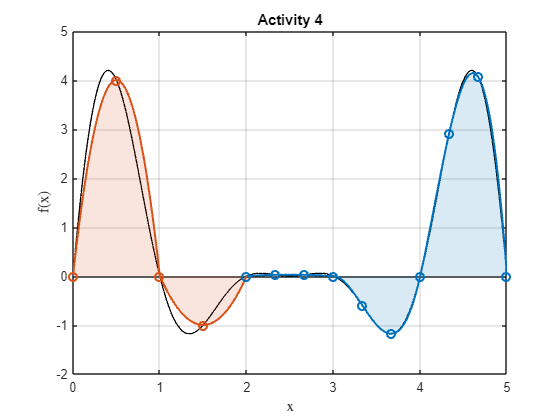

True Integral: 3.8499 
Approximate Integral:  3.9666 
Error: 3.032% 


% Select the number of intervals, n
n = 5;

% Select the function to be integrated
fx = @(x) (x-2.5).^2.*sin(pi*x);
Activity4(fx,n)

Notice how using an even number of intervals enables the Simpson's 1/3 rule (red) to be used for the entire integral approximation. Conversely, using an odd number of intervals allows us to use the Simpson's 3/8 rule (blue) for all but two of the intervals. 

#### Concept question

Notice that using a single interval enables the Simpson's 3/8 rule to provide a very accurate approximation of the integral for some functions but not others. Looking at the definition of the Simpson's 3/8 rule:


$$I \approx \left(b-a\right)\frac{f(a) + 3f(x_{1}) + 3f(x_{2}) + f(b)}{8}$$


Explain why this is the case. Under what conditions will performing the Simpson's 3/8 rule with a single interval provide a good approximation of the true integral?

### Algorithm for Simpson's 3/8 rule

The following pseudocode can be used to develop an algorithm for multiple applications of the Simpson's 3/8 rule:

Note that in this pseudocode, each interval $[x_i,x_{i+1}]$ is subdivided into 3 smaller intervals. This implies that any input $n$ can be used.

#### Activity 5: Simpson's 3/8 rule function

Use the pseudocode provided above to define a function called `Simps38` that performs the Simpson's 3/8 rule. Define the function under the **Function definitions** header below, then use your code to approximate the following integrals:

- $f(x) = e^{-0.5x} - e^{-0.25x}$ for $0\leq x \leq 20$ using $n = 2, \ n = 4, \ n=10$

- $g(x) = e^{-0.1x}\cos{\frac{\pi}{2} x}$ for $0\leq x \leq 20$ using $n = 2, \ n = 4, \ n=10$

% Call your function to compute the integrals here
a = 0;
b = 20;
% 1.
f = @(x) exp(-0.5*x) - exp(-0.25*x)

f = function_handle with value:
    @(x)exp(-0.5*x)-exp(-0.25*x)


I = Simps38(f,a,b,2)

I = -1.8789

I = Simps38(f,a,b,4)

I = -1.9642

I = Simps38(f,a,b,10)

I = -1.9729

% 2.
g = @(x) exp(-0.1*x).*cos(pi/2.*x)

g = function_handle with value:
    @(x)exp(-0.1*x).*cos(pi/2.*x)


I = Simps38(g,a,b,2)

I = 0.7402

I = Simps38(g,a,b,4)

I = -0.0527

I = Simps38(g,a,b,10)

I = 0.0323

## Function definitions

#### Simpson's 1/3 rule when f(x) is known

function I = Simpsons13(fun,a,b,n)
%Function to estimate the integral of the expression contained in fun over the interval [a,b]
%divided into n sub-intervals

% Check if n is odd
if rem(n,2) ~= 0
    error("Error: n must be an even number of intervals")
end

% Define step size h
h = (b-a)/n;

% Perform Integration
I = fun(a);
for k = 1:2:(n-2)
    % Add the new terms in the denominator
    I = I + 4*fun(k*h) + 2*fun((k+1)*h);
end
I = (h/3)*(I + 4*fun((n-1)*h) + fun(n*h));
end

#### Simpson's 1/3 rule for discrete data

function I = Simps13(x,y)
%Function to estimate the intergral of the discrete (x,y) data points.
%x should be a vector of independent variable, and y is a vector
%representing f(x) at each x coordinate

N = numel(x);

% Check if n is odd
if rem(N,2) == 0
    error("Error: The dataset must contain an odd number of data points")
end

% Check that the data is evenly spaced
if mean(diff(x,2)) ~=0
    error("Error: The dataset must contain evenly-spaced points")
end

% Points for f(x1), f(x3), ... f(x_n-1)
yOdd = y(2:2:N-1);

% Points for f(x2), f(x4), ... f(x_(n-2))
yEven = y(3:2:N-2);
numerator = y(1) + 4*sum(yOdd) + 2*sum(yEven) + y(N);
I = (x(N)-x(1))/(3*(N-1)) * numerator;

end

**Simpson's 3/8 rule**

% Write your function for the Simpson's 3/8 rule here
function I = Simps38(fx,a,b,n)
I = 0;
dx = (b-a)/n;
x = a:dx:b;
for i = 1:n
    h = (x(i+1)-x(i))/3;
    I = I + (3/8)*h*(fx(x(i)) + 3*fx(x(i)+h) + 3*fx(x(i)+2*h) + fx(x(i+1)));
end
end

**Activity helper functions**

function Activity1(a,b)

% range of x
x = linspace(0,5,1000);

% Function to be integrated
fx = @(x) 5-(x-2.5).^2 - cos(pi*x);

% Plot Function
plot(x,fx(x),LineWidth=1,SeriesIndex="none")
grid on
xlabel("x",Interpreter="latex")
ylabel("f(x)",Interpreter="latex")
title("Activity 1")

% Perform Simpson's Rule
h = (b-a)/2;
x1 = a+h;

xInt = a:h/100:b;

% Brute Force Lagrange Polynomial
f2 = ((xInt-x1).*(xInt-b))./((a-x1)*(a-b))*fx(a) + ...
    ((xInt-a).*(xInt-b))./((x1-a)*(x1-b))*fx(x1) + ...
    ((xInt-a).*(xInt-x1))./((b-a)*(b-x1))*fx(b);

% Plot Result
hold on
plot(xInt,f2,LineWidth=1.5,SeriesIndex=1)
cmap = colororder;
plot(x1,fx(x1),"o",SeriesIndex=2,MarkerFaceColor=cmap(2,:))
plot([a,b],[fx(a),fx(b)],"o",MarkerFaceColor=cmap(1,:),SeriesIndex=1)
area(xInt,f2,FaceAlpha=0.15,SeriesIndex=1)
hold off

legend("$f(x)$","$f_2(x)$","$x_1$ = " + num2str(round(x1,2)),"Interpreter","latex")

ax = gca;
ax.XAxisLocation = "origin";
ax.XTick = unique(sort([0:10,a,b],"ascend"));
ax.XTickLabel{ax.XTick == a} = "a";
ax.XTickLabel{ax.XTick == b} = "b";

end

function T = Activity2(n)
%ACTIVITY2 Defines table of k, x_k, and x_(k+1) to illustrate the
%effects of the number of intervals on the Simpson's 1/3 Rule

% Counter
k = 1:2:(n-2);

xk = string.empty(numel(k),0);
xk1 = xk;

for i = 1:numel(k)
    % Define xk
    xk(i,1) = "x_" + num2str(k(i));
    % define x_(k_1)
    xk1(i,1) = "x_" + num2str(k(i)+1);
end

k = k(:);
T = table(k,xk,xk1);
%    T.Properties.VariableNames = {'k','x_k','x_(k+1)'};
T.Properties.VariableNames = ["k" "x_k" "x_(k+1)"];
end

function Activity4(fx,n)

% range of x
x = linspace(0,5,1000);

% Plot Function
plot(x,fx(x),LineWidth=1,SeriesIndex="none")
grid on
xlabel("x",Interpreter="latex")
ylabel("f(x)",Interpreter="latex")
title("Activity 4")
hold on

% Define Data Points
h = (x(end)-x(1))/n;
x = x(1):h:x(end);

% Determine Which Method to Use
if n == 1
    h = (x(end) - x(1))/3;
    x0 = x(1);
    x3 = x(end);
    x1 = x0 + h;
    x2 = x0 + 2*h;

    p = polyfit([x0 x1 x2 x3],fx([x0 x1 x2 x3]),3);
    xint = linspace(x(1),x(end),100);
    f38 = polyval(p,xint);

    plot(xint,f38,LineWidth=1.5,SeriesIndex=1)
    plot([x0 x1 x2 x3],fx([x0 x1 x2 x3]),"o",LineWidth=1.5,SeriesIndex=1)
    area(xint,f38,FaceAlpha=0.15,SeriesIndex=1,EdgeColor="none")

    I = (3/8)*h*(fx(x0) + 3*fx(x1) + 3*fx(x2) + fx(x3));
elseif rem(n,2) == 1
    I = 0;
    % Odd number of intervals: Use 1/3 Rule for first 3 points
    for i = 1:2
        h = (x(i+1) - x(i))/2;
        x0 = x(i);
        x2 = x(i+1);
        x1 = x0 + h;

        p = polyfit([x0 x1 x2],fx([x0 x1 x2]),2);
        xint = linspace(x0,x2,100);
        f2 = polyval(p,xint);

        plot(xint,f2,LineWidth=1.5,SeriesIndex=2)
        plot([x0 x1 x2],fx([x0 x1 x2]),"o",LineWidth=1.5,SeriesIndex=2)
        area(xint,f2,FaceAlpha=0.15,SeriesIndex=2,EdgeColor="none")
        I = I + h/3*(fx(x0) + 4*fx(x1) + fx(x2));
    end
    % Now use 3/8 rule for remaining points
    for i = 3:(numel(x)-1)
        h = (x(i+1) - x(i))/3;
        x0 = x(i);
        x3 = x(i+1);
        x1 = x0 + h;
        x2 = x0 + 2*h;

        p = polyfit([x0 x1 x2 x3],fx([x0 x1 x2 x3]),3);
        xint = linspace(x(i),x(i+1),100);
        f38 = polyval(p,xint);

        plot(xint,f38,LineWidth=1.5,SeriesIndex=1)
        plot([x0 x1 x2 x3],fx([x0 x1 x2 x3]),"o",LineWidth=1.5,SeriesIndex=1)
        area(xint,f38,FaceAlpha=0.15,SeriesIndex=1,EdgeColor="none")

        I = I + (3/8)*h*(fx(x0) + 3*fx(x1) + 3*fx(x2) + fx(x3));
    end
else
    I = 0;
    % Even number of Intervals: Use 1/3 Rule
    for i = 1:(numel(x)-1)
        h = (x(i+1) - x(i))/2;
        x0 = x(i);
        x2 = x(i+1);
        x1 = x0 + h;

        p = polyfit([x0 x1 x2],fx([x0 x1 x2]),2);
        xint = linspace(x0,x2,100);
        f2 = polyval(p,xint);

        plot(xint,f2,LineWidth=1.5,SeriesIndex=2)
        plot([x0 x1 x2],fx([x0 x1 x2]),"o",LineWidth=1.5,SeriesIndex=2)
        area(xint,f2,FaceAlpha=0.15,SeriesIndex=2,EdgeColor="none")

        I = I + h/3*(fx(x0) + 4*fx(x1) + fx(x2));
    end
end
hold off

Itrue = integral(fx,0,5);

fprintf("True Integral: %2.4f \n",Itrue)
fprintf("Approximate Integral:  %2.4f \n",I)
fprintf("Error: %2.3f%% \n",abs(Itrue - I)/Itrue*100)

end
